I = imread("church.jpg");
I = rgb2gray(I);  % перевод в полутоновое
I = imrotate(I,-90);
I = im2double(I);
I_imp_noise = imnoise(I, 'salt & pepper');
I_speckle = imnoise(I,'speckle');
I_gauss = imnoise(I,"gaussian");
I_poisson = imnoise(I, 'poisson');

output_imp = AMF(I_imp_noise, 11);
output_sp = AMF(I_speckle, 11);
output_ga = AMF(I_gauss, 11);
output_po = AMF(I_poisson, 11);

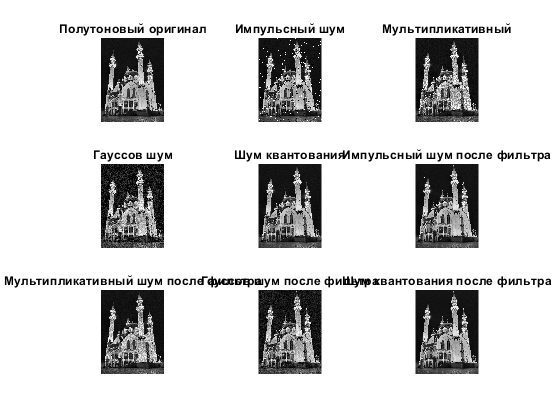

figure

subplot(3,3,1)
imshow(im2double(I))
title('Полутоновый оригинал')

subplot(3,3,2)
imshow(I_imp_noise)
title('Импульсный шум')

subplot(3,3,3)
imshow(I_speckle)
title('Мультипликативный')

subplot(3,3,4)
imshow(I_gauss)
title('Гауссов шум')

subplot(3,3,5)
imshow(I_poisson)
title('Шум квантования')

subplot(3,3,6)
imshow(output_imp)
title('Импульсный шум после фильтра')

subplot(3,3,7)
imshow(output_sp)
title('Мультипликативный шум после фильтра')

subplot(3,3,8)
imshow(output_ga)
title('Гауссов шум после фильтра')

subplot(3,3,9)
imshow(output_po)
title('Шум квантования после фильтра')

function I_rez = AMF(I,s_max)

I = im2double(I);
s = 3; 

[nrows, ncols] = size(I);

I_rez = I;
mask_base = padarray(I,[floor(s_max / 2) floor(s_max / 2)], 'symmetric');

for i = 1 : nrows
    for j = 1 : ncols
        mask = mask_base(i : i + s - 1, j : j + s - 1);
        z_min = min(mask(:));
        z_max = max(mask(:));
        z_med = median(mask(:));
        while s <= s_max
            A1 = z_med - z_min;
            A2 = z_med - z_max;
            if A1 > 0 && A2 < 0  % 1.а == True
                B1 = I(i,j) - z_min;
                B2 = I(i,j) - z_max;
                if B1 > 0 && B2 < 0
                    I_rez(i,j) = I(i,j);
                else
                    I_rez(i,j) = z_med;
                end
                break; 
            else % 1.a == False
                s = s + 2;
                if s <= s_max
                    continue
                else 
                    I_rez(i,j) = I(i,j);
                end
            end
        end
        s = 3; 
        
    end
end

end